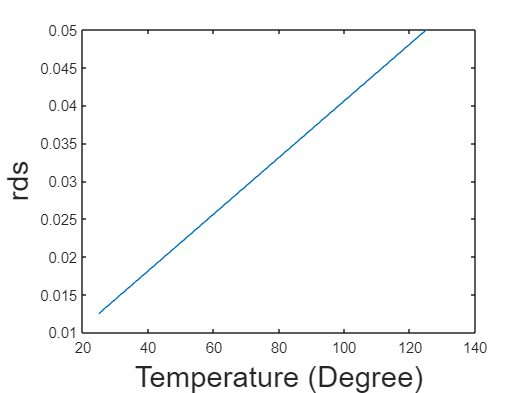

temp=25:5:125;
rds_on_temp= linspace(12.5e-3, 50e-3, length(temp));

figure()
plot(temp,rds_on_temp)
ylabel('rds',FontSize=20)
xlabel('Temperature (Degree)',FontSize=20)

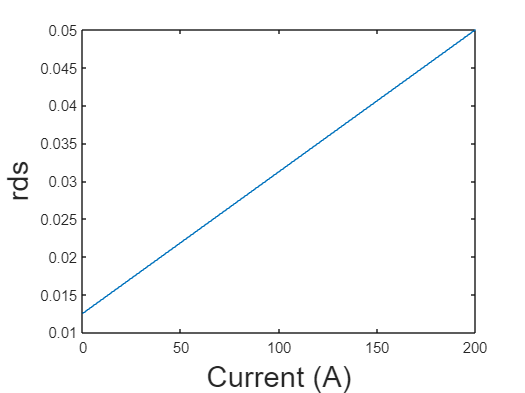


Id= 0: 5:200;
rds_on_id=linspace(12.5e-3, 50e-3, length(Id)); % linear
% rds_on_id=12.5e-3* exp(Id/100); % exponential

figure()
plot(Id,rds_on_id)
ylabel('rds',FontSize=20)
xlabel('Current (A)',FontSize=20)

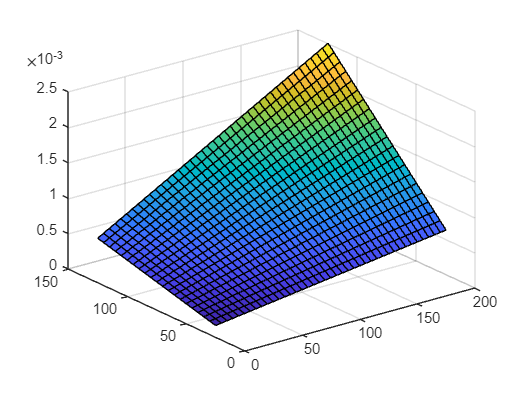



rds=[];
for i=1:length(rds_on_temp)
rds_temp=rds_on_temp(i)*rds_on_id;
rds=[rds;rds_temp];
end

[x,y] = meshgrid(Id,temp);

surf(x,y,rds)